Ripulire la memoria da variabili nell'ambiente, e ripulire la shell:

clear all;
clc

Inserire i punti noti che danno le dimensioni del profilo:

% Definizione punti noti
A = [10 7];
B = [99 100];
C = [89 100];
D = [10  39.5];
G = [51.5 54.5];
F = [64 59];
rG = 47.5;
rF = 19.5;

%% Punti curve

Individuare i punti necessari per caratterizzare il dominio del campo fluido della turbomacchina, in particolare i punti di tangenza delle curve:

% Individuazione punti curva mozzo
th = linspace(-pi/2,0, 50);
xG = G(1)+rG*cos(th);
yG = G(2)+rG*sin(th);

% Individuazione punto di tangenza
CF = sqrt((C(2)-F(2))^2+(C(1)-F(1))^2);
FT = rF;
thCF = atan((C(2)-F(2))/(C(1)-F(1)));
thCT = asin(FT/CF);
thFT = -(pi/2-thCF-thCT);

% Individuazione punti curva corona
th = linspace(thFT,-pi/2, 50);
xF = F(1)+rF*cos(th);
yF = F(2)+rF*sin(th);

T(1) = F(1)+rF*cos(thFT);
T(2) = F(2)+rF*sin(thFT);

Disegnare il dominio del campo di moto del profilo:

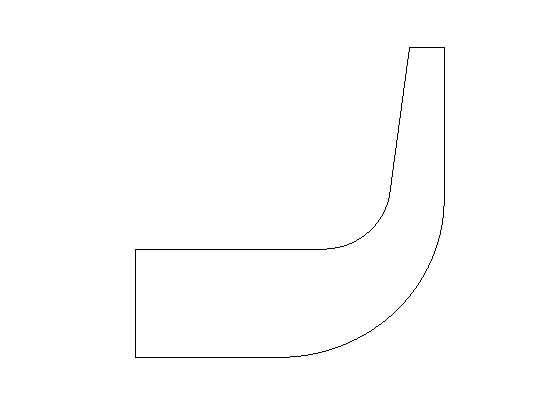

%% Disegno profilo turbomacchina
plot([A(1) B(1)], [0 0], 'r-');
hold on
axis square off
margin = 5;
axis([A(1)-margin B(1)+margin A(2)-margin B(2)+margin])
xTurbo = [A(1) G(1) xG B(1) B(1) B(1) C(1) T(1) C(1) xF F(1) D(1) D(1) A(1)];
yTurbo = [A(2) A(2) yG G(2) B(2) B(2) C(2) T(2) C(2) yF D(2) D(2) D(2) A(2)];
plot(xTurbo, yTurbo, 'k-')

Riassegnare variabili per maggior chiarezza (da mettere all'inizio):

% Variabili
xA = A(1);
yA = A(2);
xB = B(1);
yB = B(2);
xC = C(1);
yC = C(2);
xF = F(1);
yF = F(2);
xD = D(1);
yD = D(2);
xF1 = xF(1);
xF2 = T(1);
yF2 = T(2);
xG = G(1);
yG = G(2);
alpha = pi/2+thFT;

%% Discretizzazione

Si discretizza con elementi finiti che seguono la forma del dominio: impostato il numero di suddivisioni desiderate longitudinalmente $$n_{d\xi$}$ e il numero di suddivisioni in direzione trasversale $n_{d\eta }$ si procede individuando i nodi nei contorni di mozzo e corona.

Per questo programma è stato scelto di prendere nodi equidistanti nella curva. Parametrizzando la curva con ascissa curvilinea è possibile trovare facilmente le coordinate dei nodi fornendo come ascissa $\frac{k}{L_{\mathrm{curva}} }\cdot s$ con $k\in \left\lbrack 0,1,\dots ,n_{d\xi } \right\rbrack$

% Suddivisione trasversale
ndEta = 3

ndEta = 3

% Suddivisione longitudinale
ndCsi = 6*ndEta

ndCsi = 18

Nel caso della turbomacchina in questione, le parametrizzazioni per la curva del mozzo e della corona si possono esprimere come segue, dove $\alpha$ è l'angolo $\widehat{F_1 {F\text{ }F}_2 }$:


$$\[
    \bar{r}_{corona}(s) = \left\{\begin{array}{l}
            0 \leq s < x_{F_1}-x_D,                         &(x_D+s, y_D) \\
            0 \leq s'= s-(x_{F_1}-x_D)< r_F\cdot \alpha,    &(x_F+r_F\cdot sin\frac{s'}{r_F},y_F-r_F\cdot cos\frac{s'}{r_F} \\
            s''= s-(x_{F_1}-x_D+r_F \cdot \alpha)\geq 0     &(\frac{x_C-x_{F_2}}{\sqrt{(y_C-y_{F_2})^2+(x_C-x_{F_2})^2}}\cdot s'', \frac{y_C-y_{F_2}}{\sqrt{(y_C-y_{F_2})^2+(x_C-x_{F_2})^2}}\cdot s'')
    \end{array}
\]$$


%% Curva corona
% Lunghezze tratti curva corona
s1c = xF1-xD;
s2c = rF*alpha;
s3c = sqrt((xC-xF2)^2+(yC-yF2)^2);

% Lunghezza curva corona
lcc = s1c+s2c+s3c;

% Parametrizzazioni delle ascisse e ordinate della curva della corona
pXC = @(s) ((s>=0)&(s<s1c)).*       (xD+s) ...
    +      ((s>=s1c)&(s<s1c+s2c)).* (xF+rF*sin((s-s1c)/rF)) ...
    +      (s>=s1c+s2c).*           (xF2+((xC-xF2)/s3c).*(s-(s1c+s2c)));
pYC = @(s) ((s>=0)&(s<s1c)).*       (yD) ...
    +      ((s>=s1c)&(s<s1c+s2c)).* (yF-rF*cos((s-s1c)/rF)) ...
    +      (s>=s1c+s2c).*           (yF2+((yC-yF2)/s3c).*(s-(s1c+s2c)));

% Punti della curva
sCC = linspace(0, lcc, ndCsi+1);
xCC = pXC(sCC);
yCC = pYC(sCC);


$$\[
    \bar{r}_{mozzo}(s) = \left\{\begin{array}{l}
            0 \leq s < x_{G_1}-x_A,                         &(x_A+s, y_A) \\
            0 \leq s'= s-(x_{G_1}-x_A)< r_F\cdot \alpha,    &(x_G+r_G\cdot sin\frac{s'}{r_G},y_G-r_G\cdot cos\frac{s'}{r_G} \\
            s''= s-(x_{G_1}-x_A+r_G \cdot \pi/2)\geq 0      &(x_B, y_{G_2} + s'')
    \end{array}
\]$$


%% Curva mozzo
% Lunghezze tratti curva mozzo
s1m = xG-xA;
s2m = rG*pi/2;
s3m = yB-yG;

% Lunghezza curva mozzo
lcm = s1m+s2m+s3m;

% Parametrizzazioni delle ascisse e ordinate della curva del mozzo
pXC = @(s) ((s>=0)&(s<s1m)).*        (xA+s) ...
    +      ((s>=s1m)&(s<s1m+s2m)).*  (xG+rG*sin((s-s1m)/rG)) ... 
    +      (s>=s1m+s2m).*            (xB);
pYC = @(s) ((s>=0)&(s<s1m)).*        (yA) ...
    +      ((s>=s1m)&(s<s1m+s2m)).*  (yG-rG*cos((s-s1m)/rG)) ...
    +      (s>=s1m+s2m).*            (yG+(s-(s1m+s2m)));

% Punti della curva
sCM = linspace(0, lcm, ndCsi+1);
xCM = pXC(sCM);
yCM = pYC(sCM);

Infine vanno aggiunti al dominio

## Stampa dei nodi

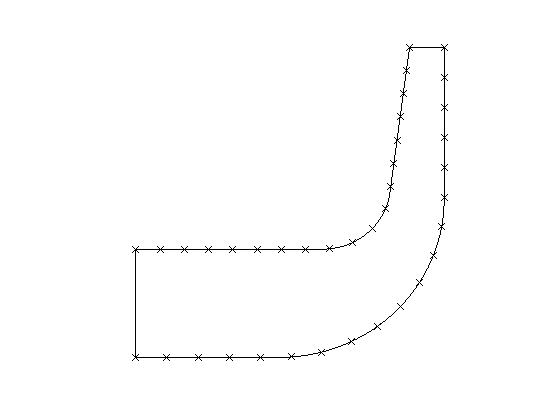


plot(xCC, yCC, 'kx');
hold on
plot(xCM, yCM, 'kx');

Dividere trasversalmente il dominio: si disegnano le rette tra i nodi appena trovati:

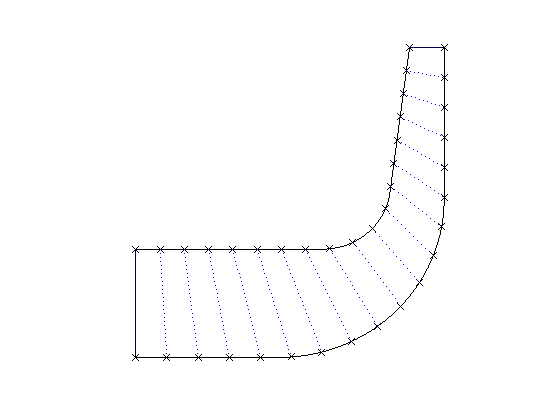

for i=1:length(sCC)
    plot([xCC(i) xCM(i)], [yCC(i) yCM(i)], 'b:')
end

Vengono passati tutti i segmenti e a loro volta vengono divisi trasversalmente. Contemporaneamente si possono costruire due vettori contenenti le coordinate $z$ e $r$ dei nodi nel dominio:

k=1;
for i=1:ndCsi+1
    for j=0:ndEta
        z(k)=(xCC(i)-xCM(i))/ndEta*j+xCM(i);
        r(k)=(yCC(i)-yCM(i))/ndEta*j+yCM(i);
%         plot(z(k), r(k), 'g+')
        k=k+1;
    end
end
% hold off

I nodi sono identificati, nell'ordine indicato in figura

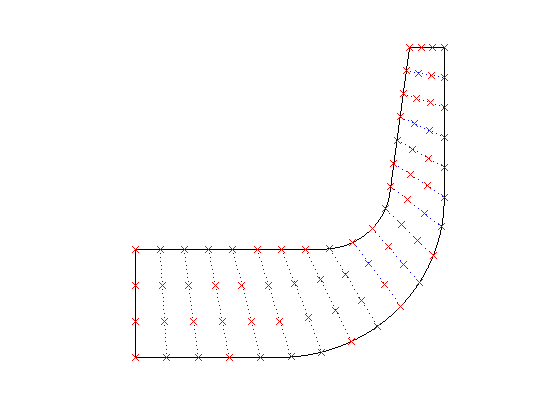

if ndCsi*ndEta < 200
    plot(xTurbo, yTurbo, 'k-')
    hold on
    axis square off
    plot(z, r, 'rx');
    for i=1:length(z)
%         text(z(i), r(i), num2str(i));
    end
    hold off
end

Ad ogni 4 nodi adiacenti viene assegnato un elemento, quadrilatero, sul quale verrà calcolata l'equazione differenziale. Per fare ciò si organizzano i nodi in una matrice.

N = zeros(ndEta+1, ndCsi+1)

N =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Ogni coefficiente della matrice avrà come valore il numero di nodo

i=1;
for k=1:ndCsi+1
   for j=1:ndEta+1
       N(j,k)=i;
       i=i+1;
   end
end
N

N =      1     5     9    13    17    21    25    29    33    37    41    45    49    53    57    61    65    69    73
     2     6    10    14    18    22    26    30    34    38    42    46    50    54    58    62    66    70    74
     3     7    11    15    19    23    27    31    35    39    43    47    51    55    59    63    67    71    75
     4     8    12    16    20    24    28    32    36    40    44    48    52    56    60    64    68    72    76


Due matrici avranno le coordinate $z$ e $r$:

i=1;
for k=1:ndCsi+1
   for j=1:ndEta+1
       zN(j,k)=z(i);
       rN(j,k)=r(i);
       i=i+1;
   end
end
zN

zN =    10.0000   18.9785   27.9570   36.9355   45.9140   54.8896   63.7316   72.1378   79.8089   86.4716   91.8885   95.8666   98.2643   99.0000   99.0000   99.0000   99.0000   99.0000   99.0000
   10.0000   18.3188   26.6376   34.9564   43.2753   51.5922   59.8200   67.7573   75.2034   81.8743   87.3458   91.2523   93.3697   94.1612   94.4623   94.7634   95.0645   95.3656   95.6667
   10.0000   17.6591   25.3183   32.9774   40.6366   48.2948   55.9084   63.3768   70.5978   77.2769   82.8032   86.6381   88.4750   89.3224   89.9246   90.5268   91.1290   91.7312   92.3333
   10.0000   16.9995   23.9989   30.9984   37.9979   44.9973   51.9968   58.9963   65.9923   72.6796   78.2605   82.0238   83.5804   84.4837   85.3869   86.2902   87.1935   88.0967   89.0000


rN

rN =     7.0000    7.0000    7.0000    7.0000    7.0000    7.1211    8.6019   11.7176   16.3575   22.3560   29.4996   37.5338   46.1723   55.1075   64.0860   73.0645   82.0430   91.0215  100.0000
   17.8333   17.8333   17.8333   17.8333   17.8333   17.9141   18.9012   20.9784   24.1056   28.7501   34.8998   42.2083   50.2330   58.5035   66.8028   75.1021   83.4014   91.7007  100.0000
   28.6667   28.6667   28.6667   28.6667   28.6667   28.7070   29.2006   30.2392   31.8538   35.1441   40.2999   46.8828   54.2937   61.8994   69.5195   77.1396   84.7598   92.3799  100.0000
   39.5000   39.5000   39.5000   39.5000   39.5000   39.5000   39.5000   39.5000   39.6020   41.5382   45.7001   51.5573   58.3544   65.2953   72.2362   79.1772   86.1181   93.0591  100.0000


Una matrice avrà i valori di $\Psi$, con applicate le condizioni di Dirichlet per mozzo e corona:

i=1;
for k=1:ndCsi+1
   for j=1:ndEta+1
       if j==1
           psiN(j,k)=0;
       else if j==ndEta+1
           psiN(j,k)=100;
       else
           psiN(j,k) = NaN;
       end
       end
       i=i+1;
   end
end
psiN

psiN =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100   100


Vengono definite le funzioni di forma, in questo contesto lineari a due dimensioni: 

%% Funzione di forma lineare
% Coordinate nel dominio locale dei nodi dell'elemento finito
csi_i = [-1 1 1 -1];
eta_i = [-1 -1 1 1];

% i = [1 2 3 4]
Ni = @(csi, eta, i) 1/4*(1+csi_i(i)*csi)*(1+eta_i(i)*eta)

Ni = function_handle with value:
    @(csi,eta,i)1/4*(1+csi_i(i)*csi)*(1+eta_i(i)*eta)


E le derivate della funzione di forma nelle due direzioni $\frac{\partial N_i }{\partial \xi }$ e $\frac{\partial N_i }{\partial \eta }$:

% Derivate funzione di forma
dNidCsi = @(eta, i) 1/4*csi_i(i)*(1+eta_i(i)*eta)

dNidCsi = function_handle with value:
    @(eta,i)1/4*csi_i(i)*(1+eta_i(i)*eta)


dNidEta = @(csi, i) 1/4*eta_i(i)*(1+csi_i(i)*csi)

dNidEta = function_handle with value:
    @(csi,i)1/4*eta_i(i)*(1+csi_i(i)*csi)


Definire le funzioni interpolanti e le loro derivate in $\xi$ e $\eta$ con un $\mathrm{for}$ risulta oneroso richiamarle, quindi vengono definite per praticità come segue:

xCsiEta = @(csi, eta, x_i) Ni(csi,eta,1)*x_i(1) + ...
                           Ni(csi,eta,2)*x_i(2) + ...
                           Ni(csi,eta,3)*x_i(3) + ...
                           Ni(csi,eta,4)*x_i(4)

xCsiEta = function_handle with value:
    @(csi,eta,x_i)Ni(csi,eta,1)*x_i(1)+Ni(csi,eta,2)*x_i(2)+Ni(csi,eta,3)*x_i(3)+Ni(csi,eta,4)*x_i(4)


% zCsiEta = xCsiEta(csi,eta,z_i)
% rCsiEta = xCsiEta(csi,eta,r_i)

dxdCsi = @(eta, x_i)       dNidCsi(eta, 1)*x_i(1) + ...
                           dNidCsi(eta, 2)*x_i(2) + ...
                           dNidCsi(eta, 3)*x_i(3) + ...
                           dNidCsi(eta, 4)*x_i(4)

dxdCsi = function_handle with value:
    @(eta,x_i)dNidCsi(eta,1)*x_i(1)+dNidCsi(eta,2)*x_i(2)+dNidCsi(eta,3)*x_i(3)+dNidCsi(eta,4)*x_i(4)


dxdEta = @(csi, x_i)       dNidEta(csi, 1)*x_i(1) + ...
                           dNidEta(csi, 2)*x_i(2) + ...
                           dNidEta(csi, 3)*x_i(3) + ...
                           dNidEta(csi, 4)*x_i(4)

dxdEta = function_handle with value:
    @(csi,x_i)dNidEta(csi,1)*x_i(1)+dNidEta(csi,2)*x_i(2)+dNidEta(csi,3)*x_i(3)+dNidEta(csi,4)*x_i(4)


% dzdCsi = dxdCsi(eta, z_i)
% dzdEta = dxdEta(csi, z_i)
% drdCsi = dxdCsi(eta, r_i)
% drdEta = dxdEta(csi, r_i)

detJ = @(csi, eta, z_i, r_i)        dxdCsi(eta, z_i)*dxdEta(csi, r_i) ...
                                  - dxdEta(csi, z_i)*dxdCsi(eta, r_i)

detJ = function_handle with value:
    @(csi,eta,z_i,r_i)dxdCsi(eta,z_i)*dxdEta(csi,r_i)-dxdEta(csi,z_i)*dxdCsi(eta,r_i)


                              
dNidz = @(csi, eta, z_i, r_i, i)    dxdEta(csi, r_i)*dNidCsi(eta, i) ...
                                  - dxdCsi(eta, r_i)*dNidEta(csi, i) ...
                                  / detJ(csi, eta, z_i, r_i)

dNidz = function_handle with value:
    @(csi,eta,z_i,r_i,i)dxdEta(csi,r_i)*dNidCsi(eta,i)-dxdCsi(eta,r_i)*dNidEta(csi,i)/detJ(csi,eta,z_i,r_i)


                              
dNidr = @(csi, eta, z_i, r_i, i)    dxdEta(csi, z_i)*dNidCsi(eta, i) ...
                                  - dxdCsi(eta, z_i)*dNidEta(csi, i) ...
                                  / detJ(csi, eta, z_i, r_i)

dNidr = function_handle with value:
    @(csi,eta,z_i,r_i,i)dxdEta(csi,z_i)*dNidCsi(eta,i)-dxdCsi(eta,z_i)*dNidEta(csi,i)/detJ(csi,eta,z_i,r_i)


Si prende un elemento aribtrario all'interno del campo fluido per controllare che la funzione di forma sia definita correttamente (i punti $\left(\xi ,\eta \right)$ mappano in $\left(z,r\right)$):

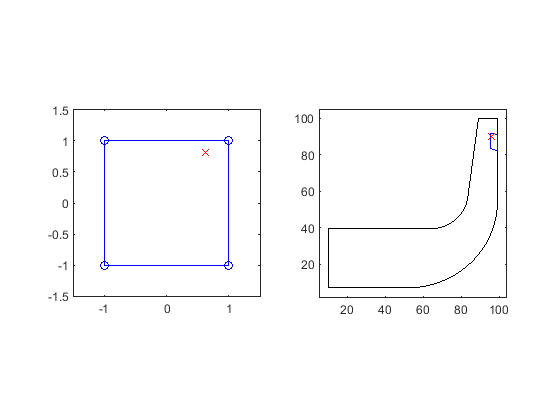

% Mappatura punto arbitrario csi, eta
csiA = -1+2*rand(1);
etaA = -1+2*rand(1);

% Grafico dominio locale
subplot(1,2,1)
plot([csi_i csi_i(1)],[eta_i eta_i(1)],'bo-')
hold on
% E del punto arbitrario
plot(csiA, etaA, 'rx')
axis square
axis([-1.5 1.5 -1.5 1.5])
hold off

% Individuazione quadrilatero n-esimo
% j e k dato l'indice del nodo
j = ceil(ndEta*rand(1));
k = ceil(ndCsi*rand(1));
z_i= [zN(j,k) zN(j,k+1) zN(j+1,k+1) zN(j+1,k)];
r_i= [rN(j,k) rN(j,k+1) rN(j+1,k+1) rN(j+1,k)];

% Calcolo delle coordinate del punto data la funzione di forma
rA=xCsiEta(csiA,etaA,r_i);
zA=xCsiEta(csiA,etaA,z_i);

%% Grafico dell'elemento nella turbomacchina
subplot(1,2,2)
plot(xTurbo, yTurbo, 'k-')
hold on
plot([z_i z_i(1)], [r_i r_i(1)], 'b-')

% Plot del punto arbitrario
plot(zA, rA, 'rx')

% % Numeri dei nodi
% text(z_i(1), r_i(1), num2str(N(j,k)))
% text(z_i(2), r_i(2), num2str(N(j,k+1)))
% text(z_i(3), r_i(3), num2str(N(j+1,k+1)))
% text(z_i(4), r_i(4), num2str(N(j+1,k)))

% Parametri grafici
axis square
axis([A(1)-margin B(1)+margin A(2)-margin B(2)+margin])
hold off

Come si può notare dal grafico, la mappatura ha successo

Calcolare i coefficienti $a_{j,i}^X$ dove $j\text{ }$ rappresenta il nodo, $i$ il nodo locale su cui viene pesato il coefficiente della funzione interpolante.

Provare prima per un coefficiente, come $a_{1,1}^I$:

xG=[-sqrt(3/5) 0 sqrt(3/5)];
pgauss=[5/9 8/9 5/9];

% xG=[-0.577350 0.577350];
% pgauss=[1 1];

subplot(1,2,1)
plot([csi_i csi_i(1)],[eta_i eta_i(1)],'bo-')
hold on
for i=1:length(xG)
    for j=1:length(xG)
        plot(xG(i), xG(j), 'r+')
    end
end
axis square
axis([-1.5 1.5 -1.5 1.5])
hold off


j = ceil((ndEta-1)*rand(1));
k = ceil((ndCsi-1)*rand(1));

z_i= [zN(j,k) zN(j,k+1) zN(j+1,k+1) zN(j+1,k)]

z_i =    18.3188   26.6376   25.3183   17.6591


r_i= [rN(j,k) rN(j,k+1) rN(j+1,k+1) rN(j+1,k)]

r_i =    17.8333   17.8333   28.6667   28.6667


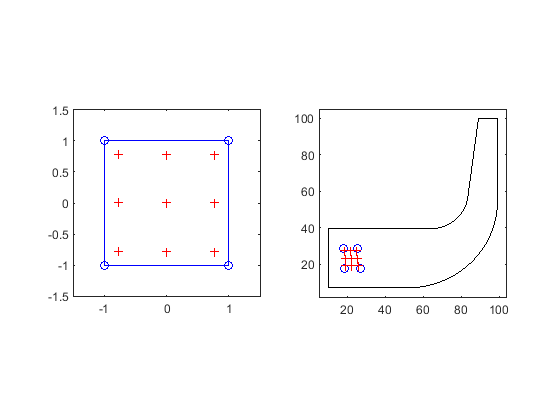



subplot(1,2,2)
plot(xTurbo, yTurbo, 'k-')
hold on
plot([z_i z_i(1)], [r_i r_i(1)], 'bo')

% aij=0;
for i=1:length(xG)
    for j=1:length(xG)
        plot(xCsiEta(xG(i),xG(j),z_i), xCsiEta(xG(i),xG(j),r_i), 'r+')
%         aij=aij + pgauss(i)*pgauss(j) ...
%             / xCsiEta(xG(i),xG(j), r_i) ... 
%             * (   dNidz(xG(i), xG(j), z_i, r_i, 1) * dNidz(xG(i), xG(j), z_i, r_i, 1) ...
%                 + dNidr(xG(i), xG(j), z_i, r_i, 1) * dNidr(xG(i), xG(j), z_i, r_i, 1))...
%             * detJ(xG(i), xG(j), z_i, r_i);
    end
end
% aij

axis square
axis([A(1)-margin B(1)+margin A(2)-margin B(2)+margin])
hold off

Ora verranno passati alcuni nodi, e, a seconda di quale contorno della matrice si trovano, verranno trovati i punti adiacenti, per trovare gli elementi corretti di cui fanno parte. Con lo stesso procedimento si troveranno i valori dei coefficienti della matrice di risoluzione del sistema nella prossima sezione:

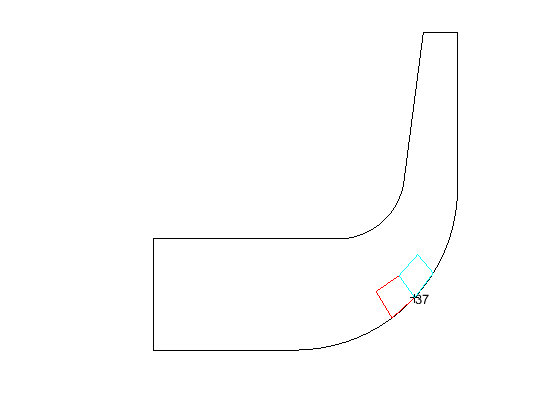

subplot(1,1,1)
plot(xTurbo, yTurbo, 'k-')
hold on
axis off square

% Punto qualsiasi
m = ceil(ndEta*rand(1));
n = ceil(ndCsi*rand(1));

plot(zN(m,n),rN(m,n), 'k+')
text(zN(m,n), rN(m,n), num2str(N(m,n)));
if n>1
    if m>1
        % In basso a sinistra
        % Peso N = 3
        m_i = [m-1 m-1 m m];
        n_i = [n-1 n n n-1];
        z_i = diag(zN(m_i,n_i))';
        r_i = diag(rN(m_i,n_i))';
        plot([z_i z_i(1)], [r_i r_i(1)], 'g-')
        clear z_i r_i;
    end
    if m<ndEta+1
        % In alto a sinistra
        % Peso N = 2
        m_i = [m m m+1 m+1];
        n_i = [n-1 n n n-1];
        z_i = diag(zN(m_i,n_i))';
        r_i = diag(rN(m_i,n_i))';
        plot([z_i z_i(1)], [r_i r_i(1)], 'r-')
        clear z_i r_i;
    end
end
if n<ndCsi+1
    if m>1
        % In basso a destra
        % Peso N = 4
        m_i = [m-1 m-1 m m];
        n_i = [n n+1 n+1 n];
        z_i = diag(zN(m_i,n_i))';
        r_i = diag(rN(m_i,n_i))';
        plot([z_i z_i(1)], [r_i r_i(1)], 'b-')
        clear z_i r_i;
    end
    if m<ndEta+1
        % In alto a destra
        % Peso N = 1        
        m_i = [m m m+1 m+1]; 
        n_i = [n n+1 n+1 n];
        z_i = diag(zN(m_i,n_i))';
        r_i = diag(rN(m_i,n_i))';
        plot([z_i z_i(1)], [r_i r_i(1)], 'c-')
        clear z_i r_i;
    end
end

hold off

Costruzione della matrice dei coefficienti $a_{j,i}$:

a = zeros(N(ndEta+1,ndCsi+1),N(ndEta+1,ndCsi+1));

m = ceil(ndEta*rand(1));
n = ceil(ndCsi*rand(1));

for n=1:ndCsi+1
    for m=1:ndEta+1
        l = N(m,n);
        if n>1
            if m>1 % ------------------------In basso a sinistra
                
                % Peso N = 3
                k = 3;
                m_i = [m-1 m-1 m m];
                n_i = [n-1 n n n-1];
                z_i = diag(zN(m_i,n_i))';
                r_i = diag(rN(m_i,n_i))';
                
                h = 3;
                a(l,l) = a(l,l) + aIntGauss(z_i, r_i, h, k);
                
                h = 2;
                a(l,N(m-1,n)) = a(l, N(m-1,n)) + aIntGauss(z_i, r_i, h, k);
                
                h = 4;
                a(l,N(m,n-1)) = a(l,N(m,n-1)) + aIntGauss(z_i, r_i, h, k);
                
                h = 1;
                a(l,N(m-1,n-1)) = a(l,N(m-1,n-1)) + aIntGauss(z_i, r_i, h, k);
                
                clear z_i r_i;
            end
            if m<ndEta+1 % ------------------In alto a sinistra
                
                % Peso N = 2
                k = 2;
                m_i = [m m m+1 m+1];
                n_i = [n-1 n n n-1];
                z_i = diag(zN(m_i,n_i))';
                r_i = diag(rN(m_i,n_i))';
                
                h = 2;
                a(l,l) = a(l,l) + aIntGauss(z_i, r_i, h, k);
                
                h = 3;
                a(l,N(m+1,n)) = a(l, N(m+1,n)) + aIntGauss(z_i, r_i, h, k);
                
                h = 1;
                a(l,N(m,n-1)) = a(l,N(m,n-1)) + aIntGauss(z_i, r_i, h, k);
                
                h = 4;
                a(l,N(m+1,n-1)) = a(l, N(m+1,n-1)) + aIntGauss(z_i, r_i, h, k);
                
                clear z_i r_i;
            end
        end
        if n<ndCsi+1
            if m>1 % ------------------------In basso a destra
                
                % Peso N = 4
                k = 4;
                m_i = [m-1 m-1 m m];
                n_i = [n n+1 n+1 n];
                z_i = diag(zN(m_i,n_i))';
                r_i = diag(rN(m_i,n_i))';
                
                h = 4;
                a(l,l) = a(l,l) + aIntGauss(z_i, r_i, h, k);
                
                h = 1;
                a(l,N(m-1,n)) = a(l, N(m-1,n)) + aIntGauss(z_i, r_i, h, k);
                
                h = 3;
                a(l,N(m,n+1)) = a(l,N(m,n+1)) + aIntGauss(z_i, r_i, h, k);
                
                h = 2;
                a(l,N(m-1,n+1)) = a(l,N(m-1,n+1)) + aIntGauss(z_i, r_i, h, k);
                
                clear z_i r_i;
            end
            if m<ndEta+1 % ------------------In alto a destra
                
                % Peso N = 1        
                k = 1;
                m_i = [m m m+1 m+1]; 
                n_i = [n n+1 n+1 n];
                z_i = diag(zN(m_i,n_i))';
                r_i = diag(rN(m_i,n_i))';
                
                h = 1;
                a(l,l) = a(l,l) + aIntGauss(z_i, r_i, h, k);
                
                h = 4;
                a(l,N(m+1,n)) = a(l, N(m+1,n)) + aIntGauss(z_i, r_i, h, k);
                
                h = 2;
                a(l,N(m,n+1)) = a(l,N(m,n+1)) + aIntGauss(z_i, r_i, h, k);
                
                h = 3;
                a(l,N(m+1,n+1)) = a(l,N(m+1,n+1)) + aIntGauss(z_i, r_i, h, k); 
                
                clear z_i r_i;
            end
        end
    end
end
a

a =    25.1921    9.6413         0         0  -25.1214   -9.7120         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    9.6413   25.9249    4.6049         0   -9.6501  -25.8840   -4.6369         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

Viene compilato un vettore con i valori di $\psi$ e il vettore dei contributi al contorno, che per condizioni di Dirichlet è nullo per ogni nodo:

i = 1;
for n=1:ndCsi+1
    for m=1:ndEta+1
        psi(i)=psiN(m,n);
        i=i+1;
    end
end
psi = psi'

psi =      0
   NaN
   NaN
   100
     0
   NaN
   NaN
   100
     0
   NaN


b = zeros(length(psi),1)

b =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Bisogna ora ridurre il sistema alle sole incognite, dato che alcuni valori di $\Psi$ ai nodi è nota, per farlo si eliminano dal sistema le righe associate ai nodi noti (in cui la funzione di corrente è nulla o al valore massimo), e le colonne associate ai nodi vengono trasportate a destra dell'equazione, in modo da avere un sistema a matrice quadrata con vettore incognite e soluzione tipico:


$$\left\lbrack A\right\rbrack \left\lbrace x\right\rbrace =\left\lbrace b\right\rbrace$$


for i=1:length(psi)
    if (psi(i)==0) || (psi(i) ==100)
        b=b-a(:,i)*psi(i);
    end
end
b

b =          0
         0
    1.9609
   -0.1682
         0
         0
    3.9218
   -0.3365
         0
         0



aold = a;
bold = b;
j=1;
i=1;
while true
    if i==length(psi)+1
        break;
    else if psi(i) == 0 || psi(i) == 100
            if j==1
                anew=aold(2:end,2:end);
                bnew=bold(2:end);
            else if j==length(aold(:,1))
                    anew=aold(1:(end-1),1:(end-1));
                    bnew=bold(1:(end-1));
                else 
                    anew=aold([1:(j-1),(j+1):end],[1:(j-1),(j+1):end]);
                    bnew=bold([1:(j-1),(j+1):end]);
                end
            end
            i=i+1;
        else
            j=j+1;
            i=i+1;
    end
    
    end
    aold=anew;
    bold=bnew;
end
asol=aold

asol =    25.9249    4.6049  -25.8840   -4.6369         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    4.6049   14.4454   -4.6079  -14.4227         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
  -25.8840   -4.6079   52.0416    9.2439  -26.0758   -4.7000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

bsol=bold

bsol =          0
    1.9609
         0
    3.9218
         0
    3.9218
         0
    3.9218
         0
    3.7995


clear aold anew bold bnew

x=asol\bsol

x =    18.7699
   53.6677
   18.7414
   53.6212
   18.6570
   53.4823
   18.5194
   53.2528
   18.3328
   52.9352


Ora che si è trovato il vettore soluzione, si può reinserire nei nodi il cui valore di $\Psi$ era incognito:

i=1;
for n=1:ndCsi+1
    for m=1:ndEta+1
        if isnan(psiN(m,n))
            psiN(m,n) = x(i);
            i=i+1;
        end
    end
end
psiN

psiN =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   18.7699   18.7414   18.6570   18.5194   18.3328   18.1130   17.9655   17.9061   17.9445   18.1612   18.6698   19.5958   21.0579   23.1661   25.8154   28.6977   31.5177   33.7301   34.5025
   53.6677   53.6212   53.4823   53.2528   52.9352   52.5387   52.1187   51.6390   51.0218   50.6910   51.1223   52.6936   55.5328   58.6615   61.6464   64.3092   66.4247   67.6764   67.4990
  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000


Rimane solamente da trovare le curve di livello della funzione $\Psi$ interpolata per un valore a piacere. In questo caso i valori saranno $5,50,95$:

plot(xTurbo, yTurbo, 'k-')
hold on
axis([min(xTurbo)-5 max(xTurbo)+5 min(yTurbo)-5 max(yTurbo)+5])
for psiX = [5 50 95]

Si trova prima la lista di punti appena al di sotto del valore cercato

clear minPsi
minPsi = zeros(ndCsi+1,1);
for n=1:ndCsi+1
    for m=1:ndEta+1
        if psiN(m,n)>psiX
            minPsi(n) = m-1;
            break
        end
    end
end

Per ogni punto della lista si prende il quadrilatero in alto a destra, e si calcola la curva di livello nel dominio locale

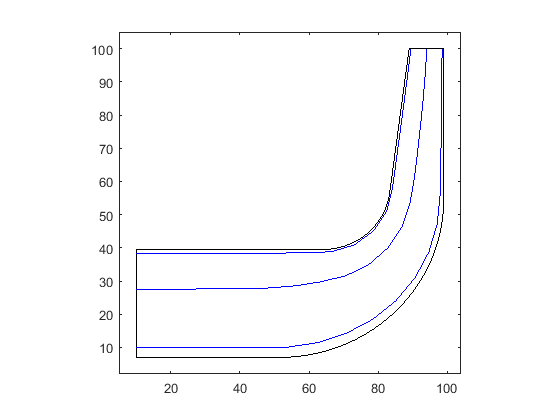

clear rPsiX zPsiX
zPsiX = zeros(1,20);
rPsiX = zPsiX;
for n=1:ndCsi
    m = minPsi(n);
    
    m_i = [m m m+1 m+1]; 
    n_i = [n n+1 n+1 n];
    z_i = diag(zN(m_i,n_i))';
    r_i = diag(rN(m_i,n_i))';
    
    psi1 = psiN(m_i(1), n_i(1));
    psi2 = psiN(m_i(2), n_i(2));
    psi3 = psiN(m_i(3), n_i(3));
    psi4 = psiN(m_i(4), n_i(4));
    
    
%     plot(z_i,r_i, 'rx')
    axis square
    
        csi = linspace(-1,1,20);
        eta = zeros(1,20);
        for i=1:20
            eta(i) = ( ...
                      4*psiX...
                    - (1-csi(i))*(psi1+psi4)...
                    - (1+csi(i))*(psi2+psi3)...
                  ) / (...
                      (1+csi(i))*(psi3-psi2)...
                    + (1-csi(i))*(psi4-psi1)...
                  );
             zPsiX(i) = xCsiEta(csi(i), eta(i), z_i);
             rPsiX(i) = xCsiEta(csi(i), eta(i), r_i);
        end
        plot(zPsiX, rPsiX, 'b')
end
end
print -depsc2 fem.eps
hold off

Viene definita qui di seguito la funzione per l'integrazione numerica nel dominio locale con estremi $z_i$ ed $r_i$: 

function [aji] = aIntGauss(z_i, r_i, h, k)
    
    csi_i = [-1 1 1 -1];
    eta_i = [-1 -1 1 1];

    Ni = @(csi, eta, i) 1/4*(1+csi_i(i)*csi)*(1+eta_i(i)*eta);
    
    dNidCsi = @(eta, i) 1/4*csi_i(i)*(1+eta_i(i)*eta);
    dNidEta = @(csi, i) 1/4*eta_i(i)*(1+csi_i(i)*csi);
    
    xCsiEta = @(csi, eta, x_i) Ni(csi, eta, 1)*x_i(1) + ...
                               Ni(csi, eta, 2)*x_i(2) + ...
                               Ni(csi, eta, 3)*x_i(3) + ...
                               Ni(csi, eta, 4)*x_i(4);

    dxdCsi = @(eta, x_i)       dNidCsi(eta, 1)*x_i(1) + ...
                               dNidCsi(eta, 2)*x_i(2) + ...
                               dNidCsi(eta, 3)*x_i(3) + ...
                               dNidCsi(eta, 4)*x_i(4);
    dxdEta = @(csi, x_i)       dNidEta(csi, 1)*x_i(1) + ...
                               dNidEta(csi, 2)*x_i(2) + ...
                               dNidEta(csi, 3)*x_i(3) + ...
                               dNidEta(csi, 4)*x_i(4);
    
    detJ = @(csi, eta, z_i, r_i)        dxdCsi(eta, z_i)...
                                      * dxdEta(csi, r_i)...
                                      - dxdEta(csi, z_i)...
                                      * dxdCsi(eta, r_i);
                                  
    dNidz = @(csi, eta, z_i, r_i, i)    dxdEta(csi, r_i)...
                                      * dNidCsi(eta, i) ...
                                      - dxdCsi(eta, r_i)...
                                      * dNidEta(csi, i) ...
                                      / detJ(csi, eta, z_i, r_i);

    dNidr = @(csi, eta, z_i, r_i, i)    dxdEta(csi, z_i)...
                                      * dNidCsi(eta, i) ...
                                      - dxdCsi(eta, z_i)...
                                      * dNidEta(csi, i) ...
                                      / detJ(csi, eta, z_i, r_i);
    
    aji=0;
    
    xG=[-sqrt(3/5) 0 sqrt(3/5)];
    pG=[5/9 8/9 5/9];
    
    for i=1:length(xG)
        for j=1:length(xG)
            aji=aji ...
                + pG(i)*pG(j) ...
                / xCsiEta(xG(i),xG(j), r_i) ... 
                * ( ...
                    dNidz(xG(i), xG(j), z_i, r_i, h)...
                  * dNidz(xG(i), xG(j), z_i, r_i, k)...
                  + dNidr(xG(i), xG(j), z_i, r_i, h)...
                  * dNidr(xG(i), xG(j), z_i, r_i, k) ...
                  ) ...
                * detJ(xG(i), xG(j), z_i, r_i);
        end
    end
end